# **NevilleTheta**

[Neville theta functions](https://en.wikipedia.org/wiki/Neville_theta_functions)

## Definition


$$\theta_c \left(x,q\right)\equiv \frac{\theta_2 \left(v,q\right)}{\theta_2 \left(0,q\right)}$$



$$\theta_d \left(x,q\right)\equiv \frac{\theta_3 \left(v,q\right)}{\theta_3 \left(0,q\right)}$$



$$\theta_n \left(x,q\right)\equiv \frac{\theta_4 \left(v,q\right)}{\theta_4 \left(0,q\right)}$$



$$\theta_s \left(x,q\right)\equiv \frac{2K\left(k\right)}{\pi }\frac{\theta_1 \left(v,q\right)}{{\theta '}_1 \left(0,q\right)}$$


where q is the nome and $v=\frac{\pi x}{2K\left(k\right)}$ [2].

Domain:  $0\le q<1\;$, $-\infty <x<\infty$.   For the specified domain, the  codomain  is the set of real numbers.

Basic features:


$$\theta_c \left(-x,q\right)=\theta_c \left(x,q\right)$$



$$\theta_d \left(-x,q\right)=\theta_d \left(x,q\right)$$



$$\theta_n \left(-x,q\right)=\theta_n \left(x,q\right)$$



$$\theta_s \left(-x,q\right)=-\theta_c \left(x,q\right)$$


Special values:

Identities:

## Syntax

Y = NevilleThetaC( U,Q)

Y = NevilleThetaD( U,Q)

Y = NevilleThetaN( U,Q)

Y = NevilleThetaS( U,Q)

y = nthc( u, q)

y = nthd( u, q)

y = nthn( u, q)

y = nths( u, q)

## Description

**Y = NevilleThetaX(U,Q)** returna the Neville theta function theta {C,D,N,S} for each element of the arrays U and Q (nome). U and Q must be real and the same size or any of them can be scalar. NevilleThetaX is the wrapper function which calls the functions **nthx** element-wise via the function **ufun2**.

**y = nthx(u,q)** return the value of the Neville theta function theta {c,d,n,s}  for argument u and the nome q. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed. **nthx** is the wrapper function which calls the functions **jthetaN and thetaN **for the actual calculation. These are the MATLAB translation of the Pascal procedures from AMath [1].

## **Numerical Examples**

**Scalar input**

Accuracy

format long
q = melnome(0.3);
x = 2.5;
[nthetac(x,q), nthetad(x,q), nthetan(x,q), nthetas(x,q)]

ans =   -0.659004666767382   0.951821966612676   1.052669335465161   0.820868795245304



[nthetac(x,q), NevilleThetaC(x,q)]

ans =   -0.659004666767382  -0.659004666767382


% Maple 0.659004666767381_54967 

[nthetad(x,q), NevilleThetaD(x,q)]

ans =    0.951821966612676   0.951821966612676


% Maple  0.951821966612675_61994

[nthetan(x,q), NevilleThetaN(x,q)]

ans =    1.052669335465161   1.052669335465161


% Maple 1.052669335465161_3637

[nthetas(x,q), NevilleThetaS(x,q)]

ans =    0.820868795245304   0.820868795245304


% Maple 0.820868795245304_00536


Special values

**Vector input**

**Matrix input**

## **Examples**

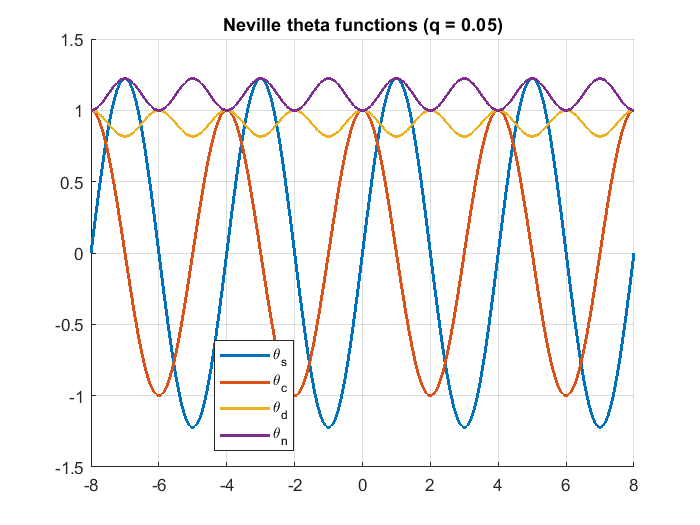

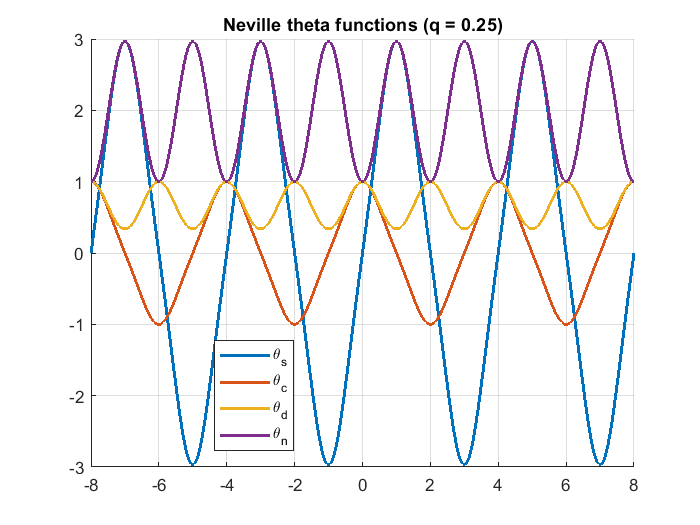

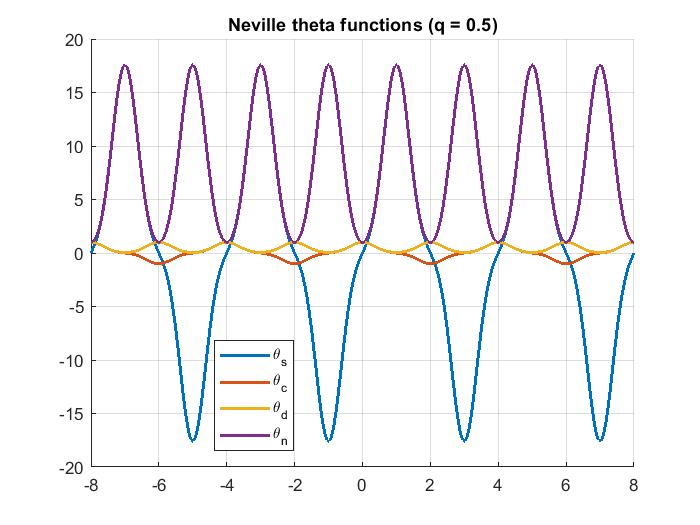

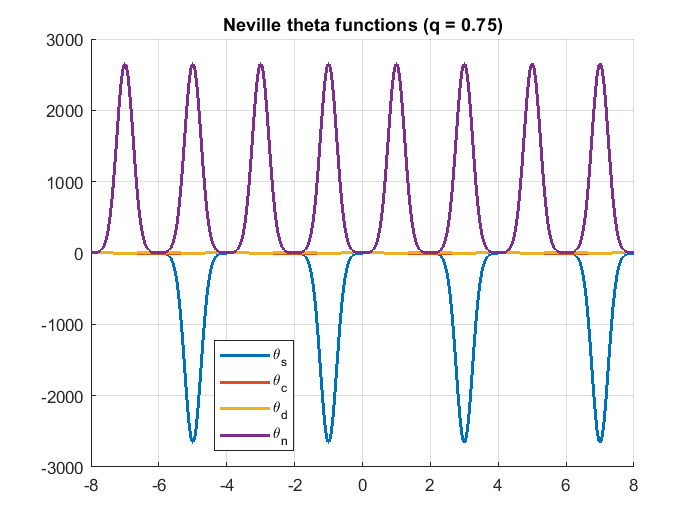

% Fig 20.14 from Beebe - The Mathematical-Function Computation Handbook,
% Springer 2017

x = -8:0.01:8;
qq = [0.05, 0.25, 0.5, 0.75];
for n = 1:4
    q = qq(n);
    figure
    clf
    hold on
    plot(x,NevilleThetaS(x*elK(ielnome(q)),q),'LineWidth',1.5)
    plot(x,NevilleThetaC(x*elK(ielnome(q)),q),'LineWidth',1.5)
    plot(x,NevilleThetaD(x*elK(ielnome(q)),q),'LineWidth',1.5)
    plot(x,NevilleThetaN(x*elK(ielnome(q)),q),'LineWidth',1.5)
    txt = sprintf('Neville theta functions (q = %g)',q);
    title(txt)
    legend('\theta_{s}','\theta_{c}','\theta_{d}','\theta_{n}',...
        'Location','best') %,'FontSize',14)
    grid on
    hold off
end

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Theta Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/20)

[Theta function, Wikipedia](https://en.wikipedia.org/wiki/Theta_function)

## **References**

[1] W.Ehrhardt, "The AMath and DMath Special functions", 2016

[2] N.H.F. Beebe - The Mathematical-Function Computation Handbook, Springer 2017

## See Also